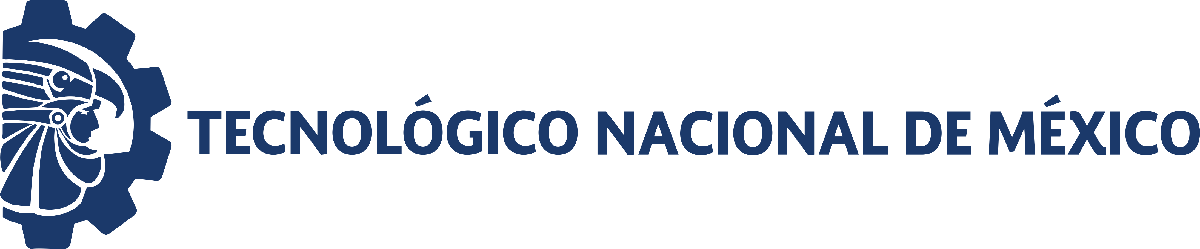                                 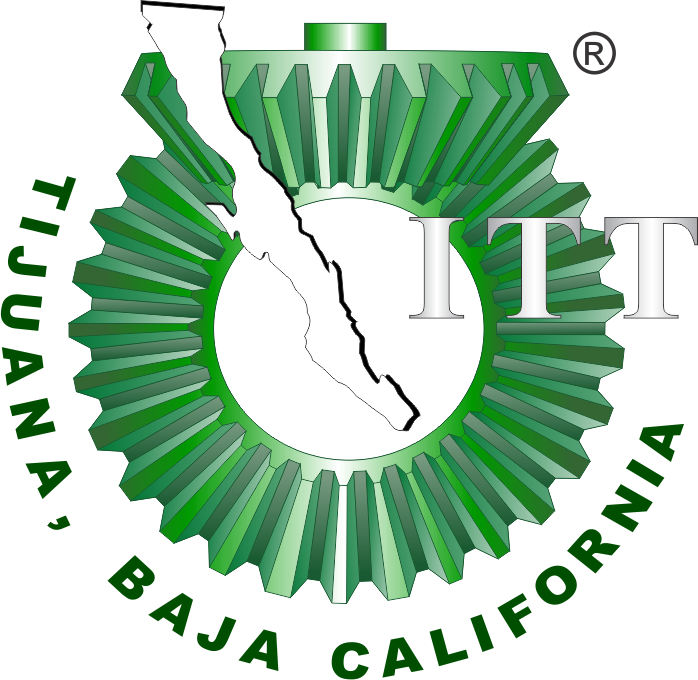

# Práctica 4: Sistema muscoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

## 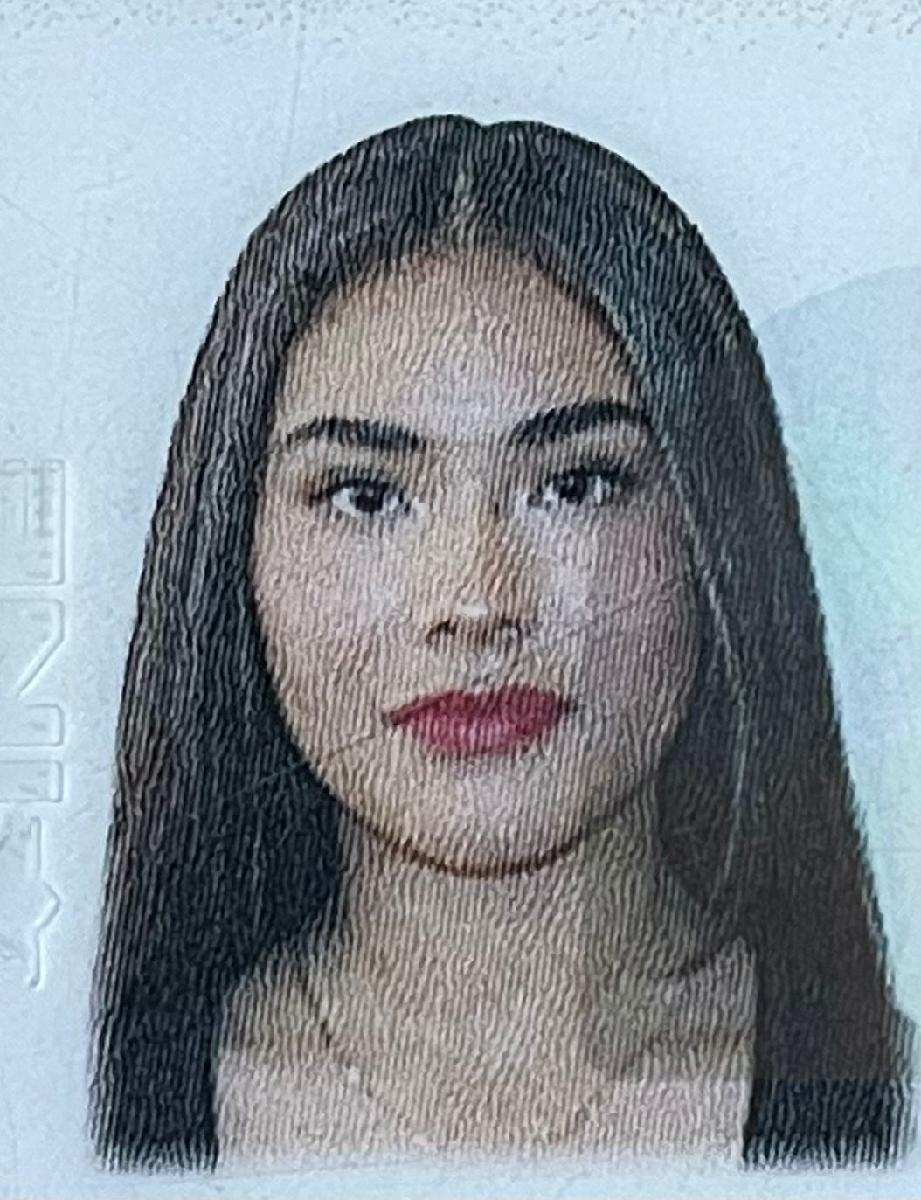

Nombre del alumno: **Karla Valeria Garcia Murillo**

Número de control: **22212385**

Correo institucional: **l22212385@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; warning('off','all')
tend = '10';
file = 'practica3' ;
open_system(file);
parameters.StopTime= tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('practica3/F(t)','PulseType','Time based');
set_param('practica3/F(t)','TimeSource','Use simulation time');
set_param('practica3/F(t)','Amplitude','1');
set_param('practica3/F(t)','Period','10');
set_param('practica3/F(t)','PulseWidth','10');
set_param('practica3/F(t)','PhaseDelay','1');
x = sim(file,parameters);
writematrix(x.F,'signal.xlsx')

## Lazo abierto

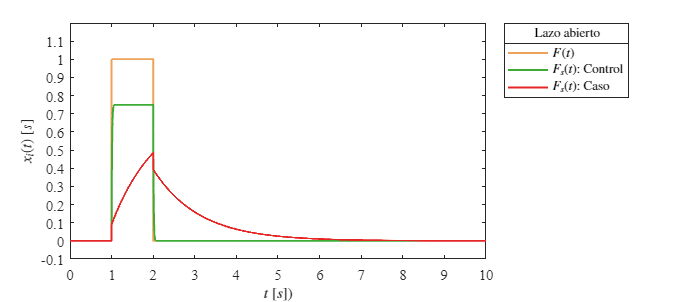


plotsignals(x.t,x.F,x.Fs1,x.Fs2)

## Lazo cerrado

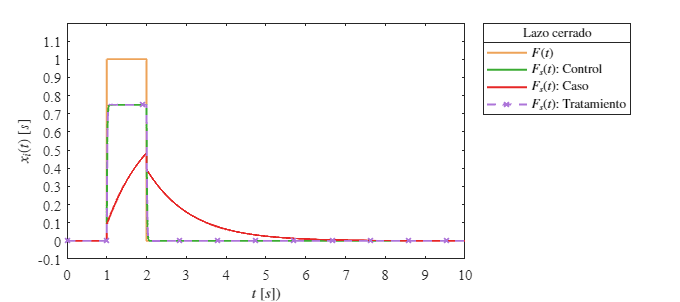


plotsignals1(x.t,x.F,x.Fs1,x.Fs2,x.Fs3)

## Función: Respuesta a las señales

function plotsignals(t,F,Fs1,Fs2,Signal)
    set(figure(),"color","w")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

   
    
    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',...
       'Linewidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3), 'Linewidth',1.5)
    L = legend('$F(t)$','$F_s(t)$: Control', '$F_s(t)$: Caso');
    set(L,'Interpreter','latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,['Lazo abierto'],'FontSize',10)

    xlabel('$t$ $[s]$)', 'Interpreter', 'latex', 'FontSize',11)
    ylabel('$x_i(t)$ $[s]$', 'Interpreter', 'latex', 'FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1 1.2]); yticks(-0.1:0.1:1.1);


    exportgraphics(gcf,['sm_lazoabierto.pdf'],'ContentType','vector')
    exportgraphics(gcf,['sm_lazoabierto.png'],'ContentType','vector')
end

function plotsignals1(t,F,Fs1,Fs2,Fs3,Signal)
    set(figure(),"color","w")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

   
    
    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,'--x',...
       'Linewidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(4), 'Linewidth',1.5)
    L = legend('$F(t)$','$F_s(t)$: Control', '$F_s(t)$: Caso','$F_s(t)$: Tratamiento');
    set(L,'Interpreter','latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,['Lazo cerrado'],'FontSize',10)

    xlabel('$t$ $[s]$)', 'Interpreter', 'latex', 'FontSize',11)
    ylabel('$x_i(t)$ $[s]$', 'Interpreter', 'latex', 'FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1 1.2]); yticks(-0.1:0.1:1.1);


    exportgraphics(gcf,['sm_lazocerrado.pdf'],'ContentType','vector')
    exportgraphics(gcf,['sm_lazocerrado.png'],'ContentType','vector')
end